clc
clear
close all

% initial values 
sample = 15000;
est_pi = zeros(1, sample); % initial pi estimations
abs_error = zeros(1, sample);
inside = 0;

cx = 0.5; cy = 0.5;        % center of circle

% for the time vs points plot (capture every 1000 points)
sampleNs = 1000:1000:sample;
cum_time = zeros(size(sampleNs));

t0 = tic;
for i = 1:sample
    x = rand; 
    y = rand;

    dx = x - cx; 
    dy = y - cy;
    if dx*dx + dy*dy <= 0.25
        inside = inside + 1;
    end
    cur_est       = 4 * inside / i;
    est_pi(i)     = cur_est;
    abs_error(i)  = abs(pi - cur_est);

    % record elapsed time at 1000,2000,...,10000
    if mod(i,1000) == 0
        cum_time(i/1000) = toc(t0);
    end
end
t_convergence = toc(t0);
n_axis = (1:sample).';

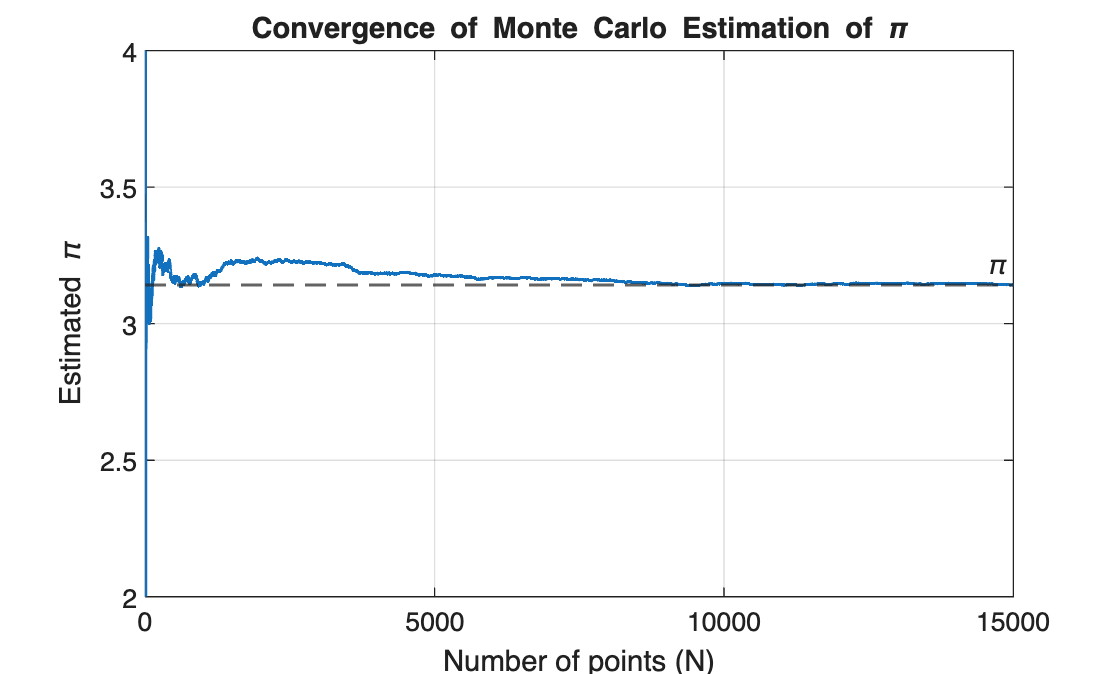

% estimated π vs number of points plot
figure;
plot(n_axis, est_pi, 'LineWidth', 1.2); hold on
yline(pi,'--','\pi','LineWidth',1.2)
xlabel('Number of points (N)')
ylabel('Estimated \pi')
title('Convergence of Monte Carlo Estimation of \pi')
grid on

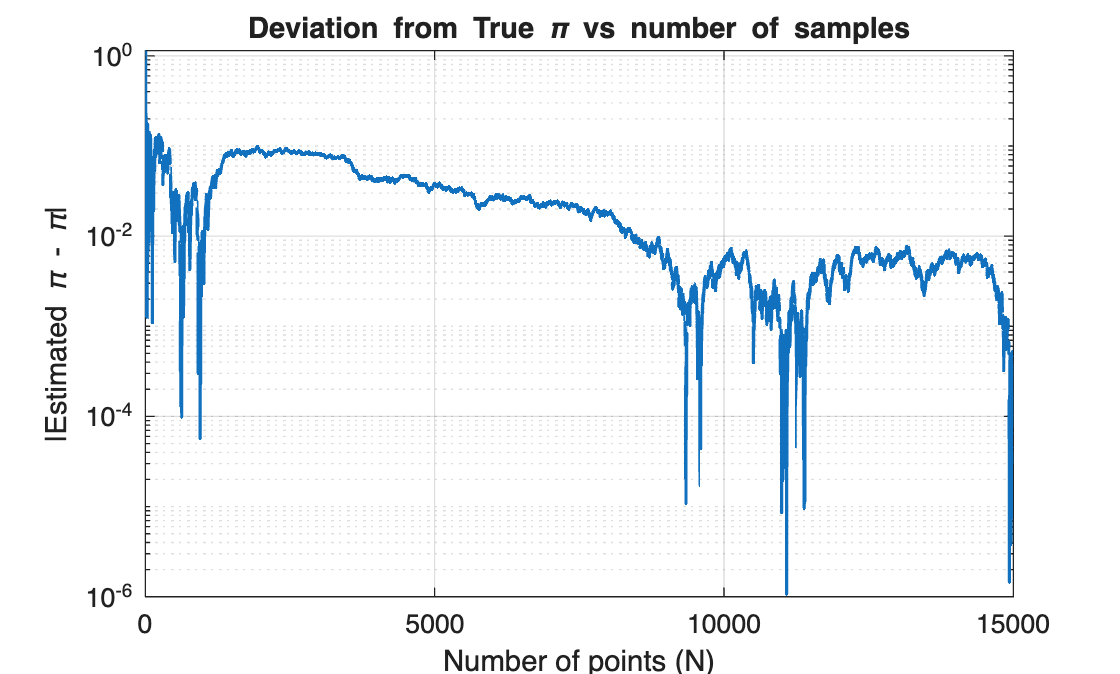

% absolute deviation from true π vs number of points (log-y for clarity)
figure;
semilogy(n_axis, abs_error, 'LineWidth', 1.2)
xlabel('Number of points (N)')
ylabel('|Estimated \pi - \pi|')
title('Deviation from True \pi vs number of samples')
grid on

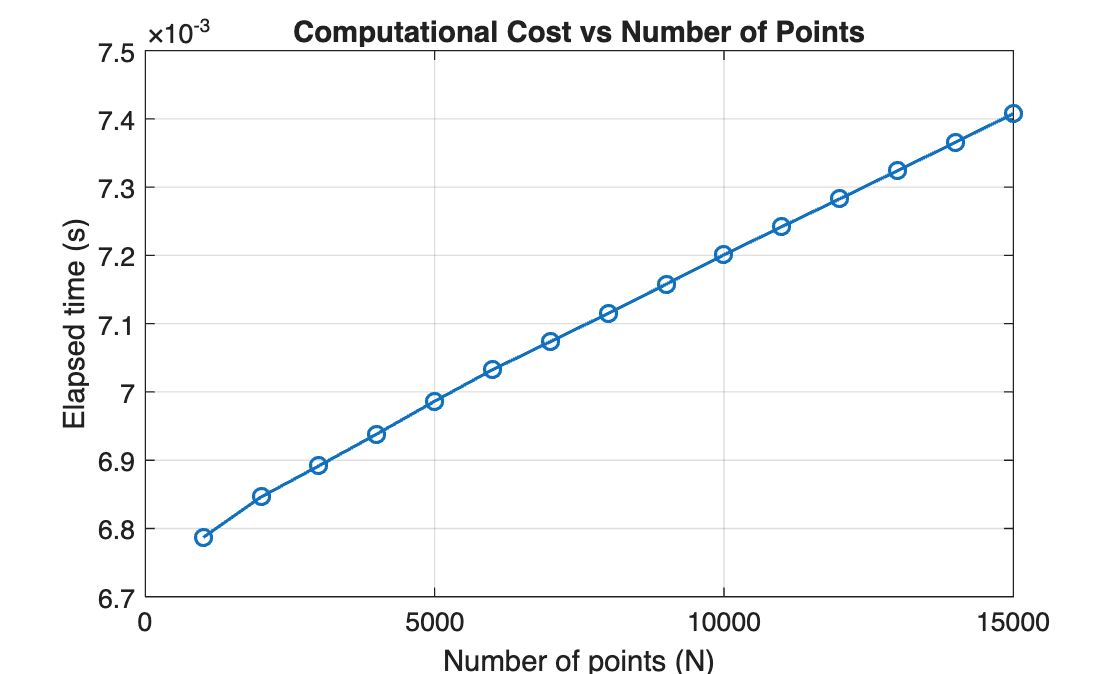

% computational time
figure;
plot(sampleNs, cum_time, 'o-', 'LineWidth', 1.2, 'MarkerSize', 6);
xlabel('Number of points (N)');
ylabel('Elapsed time (s)');
title('Computational Cost vs Number of Points');
grid on